## NEW PROBLEM

rng(1991)
sys = zpk([],[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i)],1,1);
sspace = ss(sys)

sspace =
 
  A = 
            x1       x2
   x1     0.45        1
   x2  -0.6075     0.45
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



y = impulse(sys,29)

y =          0
         0
    1.0000
    0.9000
    0.0000
   -0.7290
   -0.6561
   -0.0000
    0.5314
    0.4783


y = y(4:end)

y =     0.9000
    0.0000
   -0.7290
   -0.6561
   -0.0000
    0.5314
    0.4783
    0.0000
   -0.3874
   -0.3487


sigma = randn(length(y),1)*0.1;
yend = y(1:end)+sigma;
n = (length(yend)+1)/2;
[y, yend, y-yend]

ans =     0.9000    0.9040   -0.0040
    0.0000   -0.0870    0.0870
   -0.7290   -0.7444    0.0154
   -0.6561   -0.6894    0.0333
   -0.0000   -0.0374    0.0374
    0.5314    0.6452   -0.1138
    0.4783    0.3489    0.1294
    0.0000   -0.0867    0.0867
   -0.3874   -0.4877    0.1003
   -0.3487   -0.2576   -0.0910


rank(y(hankel(1:n,n:end)))

ans = 2

svd(y(hankel(1:n,n:end)))'

ans =     2.7500    2.4005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


rank(yend(hankel(1:n,n:end)))

ans = 14

svd(yend(hankel(1:n,n:end)))'

ans =     3.0244    2.7040    0.6084    0.5957    0.5865    0.5094    0.5083    0.3863    0.2970    0.2565    0.2513    0.2440    0.0907    0.0722


%Original System's Poles
[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i)]'

ans =    0.4500 + 0.7794i
   0.4500 - 0.7794i


%Initial System Determination
H = yend(hankel(1:n,n:end));
r=n;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3604    0.7993    0.0404    0.0124    0.0049   -0.0130   -0.0618   -0.0084   -0.0493    0.0227   -0.0024   -0.0376   -0.0015   -0.0423
   -0.7993    0.5196   -0.0694   -0.0294    0.0250    0.0200    0.0355    0.0492    0.0406   -0.0146    0.0102    0.0490    0.0050    0.0599
   -0.0405   -0.0696   -0.2235   -0.8486    0.1418    0.2872   -0.2994    0.1640   -0.1127    0.0374    0.0216    0.0084    0.0081   -0.0052
    0.0125    0.0294    0.8486   -0.3046    0.3356   -0.1077    0.2072   -0.0316    0.0788   -0.0259   -0.0031    0.0273   -0.0014    0.0343
   -0.0049    0.0231    0.1368   -0.3367   -0.8422   -0.3121    0.1902   -0.4006    0.1044   -0.0621   -0.0418   -0.0082   -0.0597   -0.0699
    0.0130    0.0217    0.2919    0.1087   -0.3104    0.0063   -0.6996    0.5925    0.0416    0.0364    0.0553    0.0853    0.0593    0.1676
   -0.0621   -0.0398    0.2888    0.2050   -0.1790    0.6853   -0.1618   -0.6120    0.1330   -0.1054   -0.0387    0.0890   -0.1098   -0.0692
    0.008

C = Gamma(1,:)

C =    -0.9758   -0.2230    0.1779    0.0790    0.0029   -0.0833   -0.1960    0.0077   -0.1764    0.0968   -0.0068   -0.1630    0.0216   -0.1369


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    1.0947 + 0.0000i
   0.6952 + 0.5693i
   0.6952 - 0.5693i
   0.4341 + 0.7839i
   0.4341 - 0.7839i
  -0.0884 + 1.0022i
  -0.0884 - 1.0022i
   0.1934 + 0.0000i
  -0.4978 + 0.8666i
  -0.4978 - 0.8666i


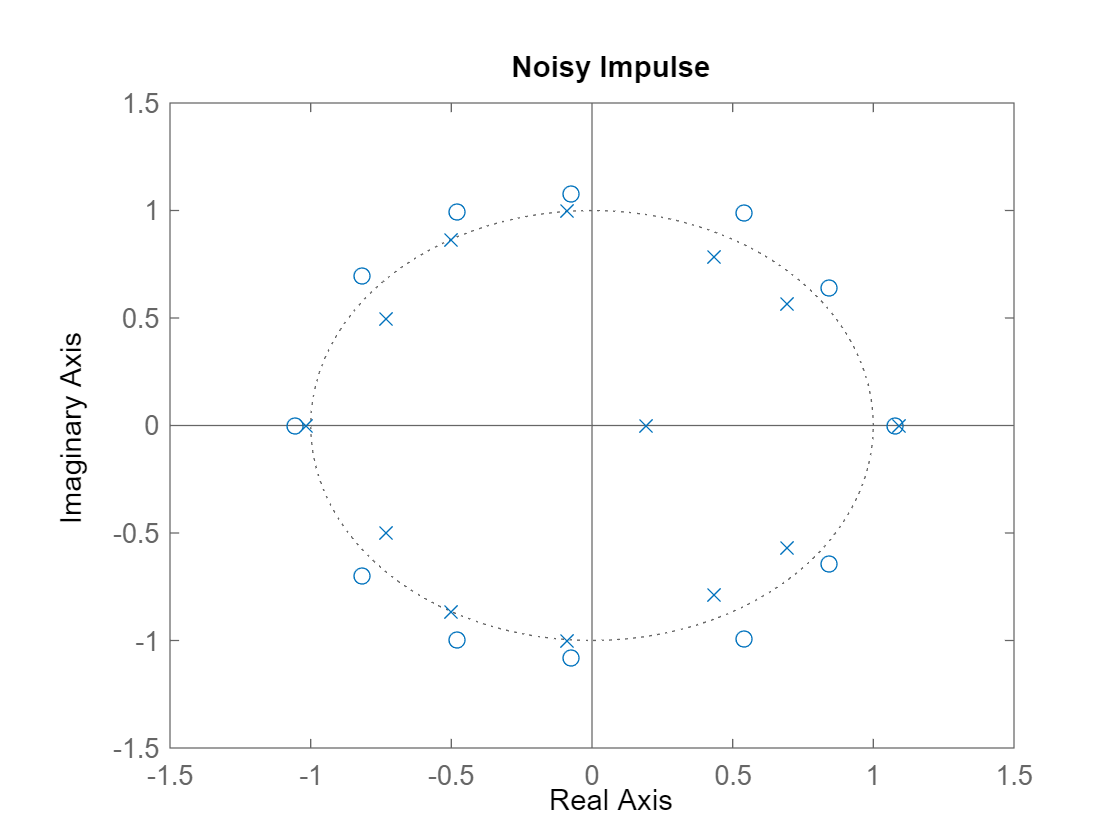

pzmap(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Noisy Impulse")

%Recovered from Optimization
y_afba = [0.665494648785641, 0.022034138651319514, -0.5366663864413213, -0.5258809312683912, -0.04764719330889952, 0.3954914782912253, 0.41385553433712396, 0.059991661873159206, -0.28997349089504026, -0.3244286601563553, -0.06383261810311223, 0.21142693181512767, 0.2533799078008744, 0.06245566863784976, -0.15320970587294008, -0.1971815416873462, -0.05808953354048729, 0.11025928709412536, 0.1529139611911357, 0.05221470640937562, -0.07873003855517996, -0.11818132863495345, -0.045787484078279955, 0.055710719472345155, 0.09103214482785696, 0.03940151131193674, -0.0390052251666344]';
H = y_afba(hankel(1:n,n:end));
r=2;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3908    0.7880
   -0.7880    0.5547


C = Gamma(1,:)

C =    -0.8348   -0.1770


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    0.4728 + 0.7837i
   0.4728 - 0.7837i


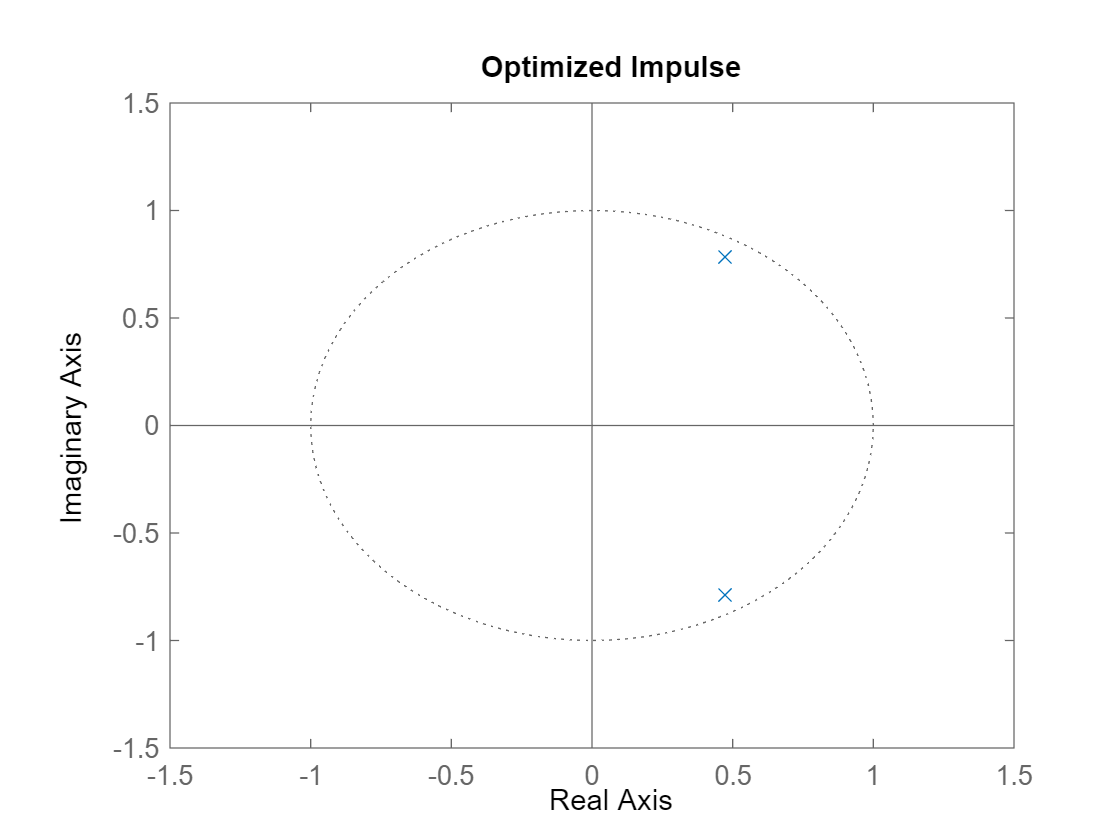

pzplot(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Optimized Impulse")

ss(sys)

ans =
 
  A = 
            x1       x2
   x1     0.45        1
   x2  -0.6075     0.45
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



zero(sys)


ans =

  0×1 empty double column vector



pole(sys)

ans =    0.4500 - 0.7794i
   0.4500 + 0.7794i


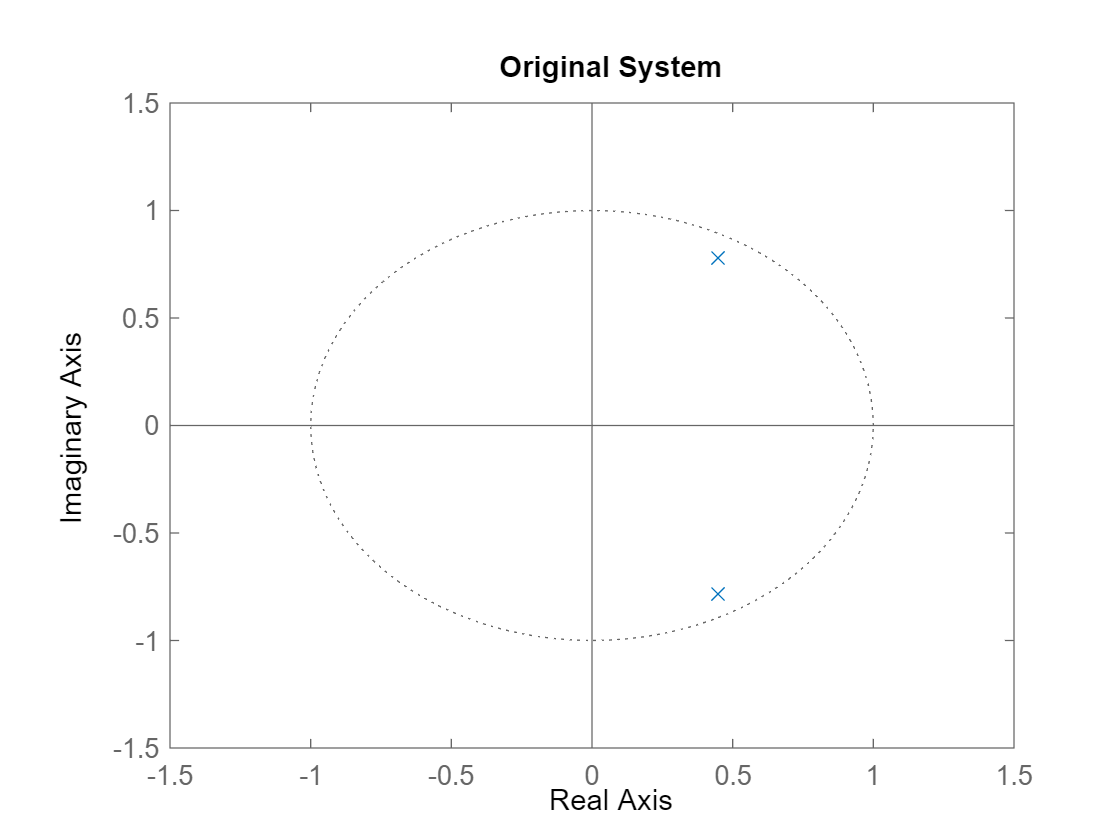

pzplot(sys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Original System")

## NEW PROBLEM

rng(1991)
sys = zpk([],[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i) -0.5*(1-sqrt(2)*i) -0.5*(1+sqrt(2)*i)],1,1);
sspace = ss(sys)

sspace =
 
  A = 
            x1       x2       x3
   x1     -0.5        1        0
   x2     -0.5     -0.5        1
   x3        0        0     0.45
   x4        0        0  -0.6075
 
            x4
   x1        0
   x2        0
   x3        1
   x4     0.45
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



y = impulse(sys,29)

y =          0
         0
         0
         0
    1.0000
   -0.1000
   -0.6500
   -0.0040
   -0.1646
    0.1676


y = y(4:end)

y =          0
    1.0000
   -0.1000
   -0.6500
   -0.0040
   -0.1646
    0.1676
    0.4873
   -0.1347
   -0.2308


sigma = randn(length(y),1)*0.1;
yend = y(1:end)+sigma;
n = (length(yend)+1)/2;
[y, yend, y-yend]

ans =          0    0.0040   -0.0040
    1.0000    0.9130    0.0870
   -0.1000   -0.1154    0.0154
   -0.6500   -0.6833    0.0333
   -0.0040   -0.0414    0.0374
   -0.1646   -0.0508   -0.1138
    0.1676    0.0382    0.1294
    0.4873    0.4006    0.0867
   -0.1347   -0.2350    0.1003
   -0.2308   -0.1397   -0.0910


rank(y(hankel(1:n,n:end)))

ans = 4

svd(y(hankel(1:n,n:end)))'

ans =     1.8456    1.7257    1.0497    0.8957    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


H = y(hankel(1:n,n:end));
r=4;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3813    0.7072    0.3390   -0.2461
   -0.7072   -0.1822    0.4598   -0.2776
   -0.3390    0.4598    0.1577    0.6641
   -0.2461    0.2776   -0.6641   -0.4569


C = Gamma(1,:)

C =    -0.7372    0.6753   -0.2982    0.0387


B = Delta(:,1)

B =    -0.7372
   -0.6753
    0.2982
    0.0387


sys2=ss(A,B,C,0,1)

sys2 =
 
  A = 
            x1       x2       x3
   x1   0.3813   0.7072    0.339
   x2  -0.7072  -0.1822   0.4598
   x3   -0.339   0.4598   0.1577
   x4  -0.2461   0.2776  -0.6641
 
            x4
   x1  -0.2461
   x2  -0.2776
   x3   0.6641
   x4  -0.4569
 
  B = 
            u1
   x1  -0.7372
   x2  -0.6753
   x3   0.2982
   x4  0.03872
 
  C = 
            x1       x2       x3
   y1  -0.7372   0.6753  -0.2982
 
            x4
   y1  0.03872
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



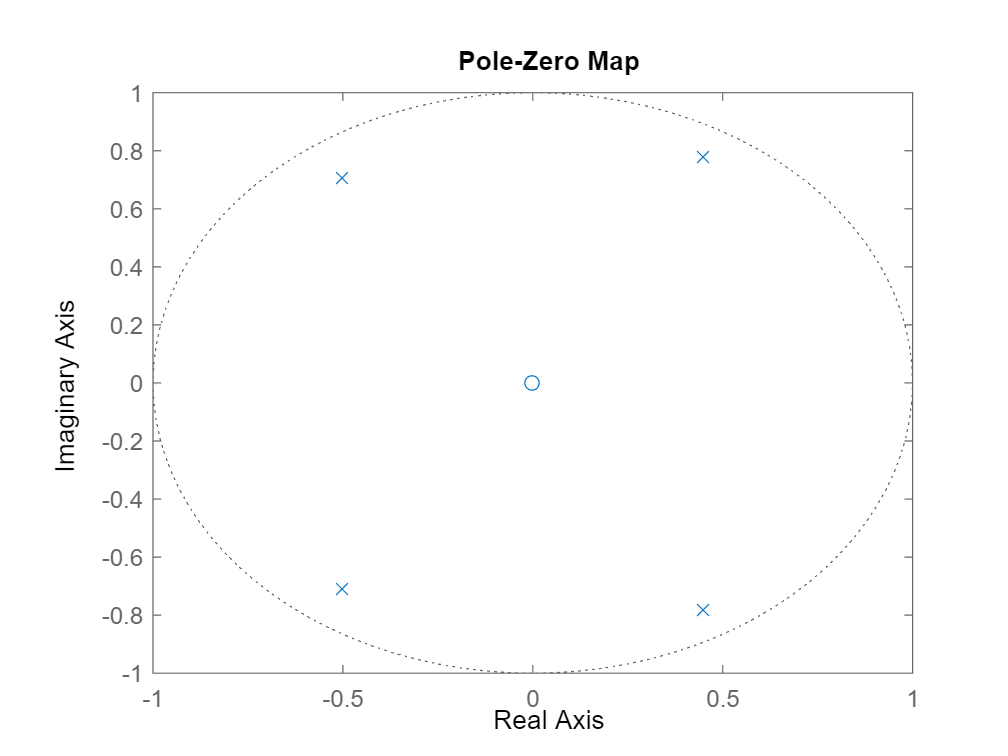

pzplot(sys2)

tf(sys2)

ans =
 
                                    
       z^2 - 1.423e-16 z - 4.011e-17
                                    
  ---------------------------------------
                                         
  z^4 + 0.1 z^3 + 0.66 z^2 + 0.135 z     
                                         
                                 + 0.6075
                                         
 
Sample time: 1 seconds
Discrete-time transfer function.



rank(yend(hankel(1:n,n:end)))

ans = 14

svd(yend(hankel(1:n,n:end)))'

ans =     1.7161    1.6568    0.9842    0.9702    0.5901    0.5234    0.5020    0.4348    0.2483    0.2451    0.2291    0.2110    0.1197    0.0622


%Initial System Determination
H = yend(hankel(1:n,n:end));
r=n;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3254   -0.7183    0.2813    0.3299   -0.0283    0.0024    0.0628    0.0139    0.0051   -0.0177   -0.0078   -0.0184   -0.0022   -0.0218
    0.7192   -0.2455   -0.2763   -0.4242    0.0442   -0.0172   -0.1024    0.0503   -0.0015    0.0122    0.0130   -0.0179    0.0328   -0.0196
    0.2796    0.2760   -0.4937    0.6683    0.0087    0.1918   -0.0076   -0.0045   -0.0466    0.1021    0.0387    0.2080    0.0585    0.0425
   -0.3295   -0.4255   -0.6708    0.1333   -0.1520   -0.1586    0.0375   -0.0727    0.0414   -0.0905   -0.0354   -0.1504   -0.1185    0.0252
    0.0252    0.0422   -0.0116   -0.1575   -0.6871    0.4835    0.4669   -0.3716   -0.0368    0.0673   -0.0043    0.2156   -0.0447    0.1201
    0.0017    0.0147    0.1874    0.1565   -0.4763   -0.0889   -0.7473   -0.3730   -0.0191    0.0515   -0.0008    0.0834   -0.0062    0.0797
   -0.0636   -0.1051    0.0028    0.0353    0.4748    0.7472   -0.1984   -0.3189    0.0327   -0.0654   -0.0178   -0.0745   -0.1531    0.0839
   -0.010

C = Gamma(1,:)

C =    -0.7088   -0.6556   -0.1359   -0.2251    0.0705    0.1182   -0.1017    0.0823   -0.0436    0.1035    0.0498    0.1595    0.1199   -0.0132


B = Delta(:,1)

B =    -0.7088
    0.6556
   -0.1359
    0.2251
   -0.0705
    0.1182
    0.1017
   -0.0823
    0.0436
    0.1035


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    1.1076 + 0.0000i
   0.7218 + 0.5472i
   0.7218 - 0.5472i
   0.4229 + 0.7633i
   0.4229 - 0.7633i
  -0.0674 + 0.9744i
  -0.0674 - 0.9744i
  -0.1583 + 0.0000i
  -0.6267 + 0.7518i
  -0.6267 - 0.7518i


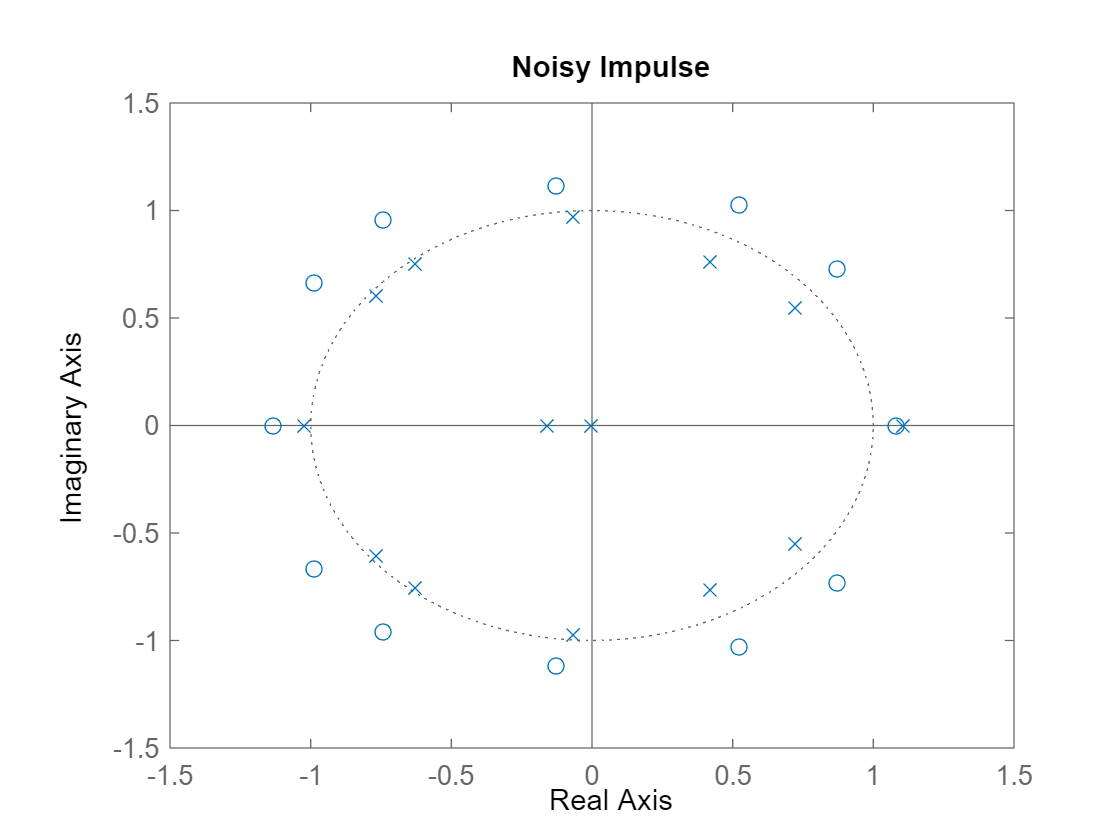

pzmap(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Noisy Impulse")

%Recovered from Optimization
y_afba = [0.031593464796497814, 0.6130263328375509, -0.006480713191293758, -0.38332206048564504, 0.009378859904633288, -0.06375571532114956, 0.09776055889011631, 0.21161179944777056, -0.14036523201587986, -0.0801664307727791, 0.03338011070844618, -0.04213266294921505, 0.08401860375690148, 0.03409103630064907, -0.08101979618197006, 0.01255452935278499, -0.0001047104023862988, -0.01080687756243423, 0.045143733397203956, -0.016204441829472185, -0.02319135109275991, 0.016826120688024984, -0.011149274417427829, 0.005802931664201195, 0.014680493261144142, -0.01639313335036452, 0.000757365584589692]';
y_afba = [0.04459000978913083, 0.6130263328375509, -0.04856298114151177, -0.38332206048564504, -0.02333240579448056, 0.05737654142079857, 0.043331220838699024, 0.100593647566248, -0.013827511757350195, -0.09587735006572666, -0.01576440550402265, 0.03238220702141661, 0.020471699691811854, 0.013016314225697647, -0.008264316115145772, -0.022154216129253782, -0.0036219929317325324, 0.011209797610193374, 0.006907770866759283, 0.0004985128293957709, -0.003785441706745492, -0.004830810997730945, -0.00020168169892618027, 0.0033612165356693064, 0.0018811582663284107, -0.0005291436509906086, -0.0013814620435846096]';
H = y_afba(hankel(1:n,n:end));
r=4;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma);
Delta = (Sigma^0*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3309    0.6827    0.1411   -0.0882
   -0.7467   -0.2306    0.1905   -0.1063
   -0.4324    0.5334    0.3153    0.5593
   -0.3692    0.4065   -0.7641   -0.3171


C = Gamma(1,:)

C =    -0.5623    0.4769   -0.0996    0.0257


B = Delta(:,1)

B =    -0.6304
   -0.5849
    0.3420
    0.1206


newsys = ss(A,B,C,0,1);
pole(newsys)

ans =    0.3696 + 0.7172i
   0.3696 - 0.7172i
  -0.3204 + 0.6713i
  -0.3204 - 0.6713i


zero(newsys)

ans =  -13.7821 + 0.0000i
   0.0662 + 0.3302i
   0.0662 - 0.3302i


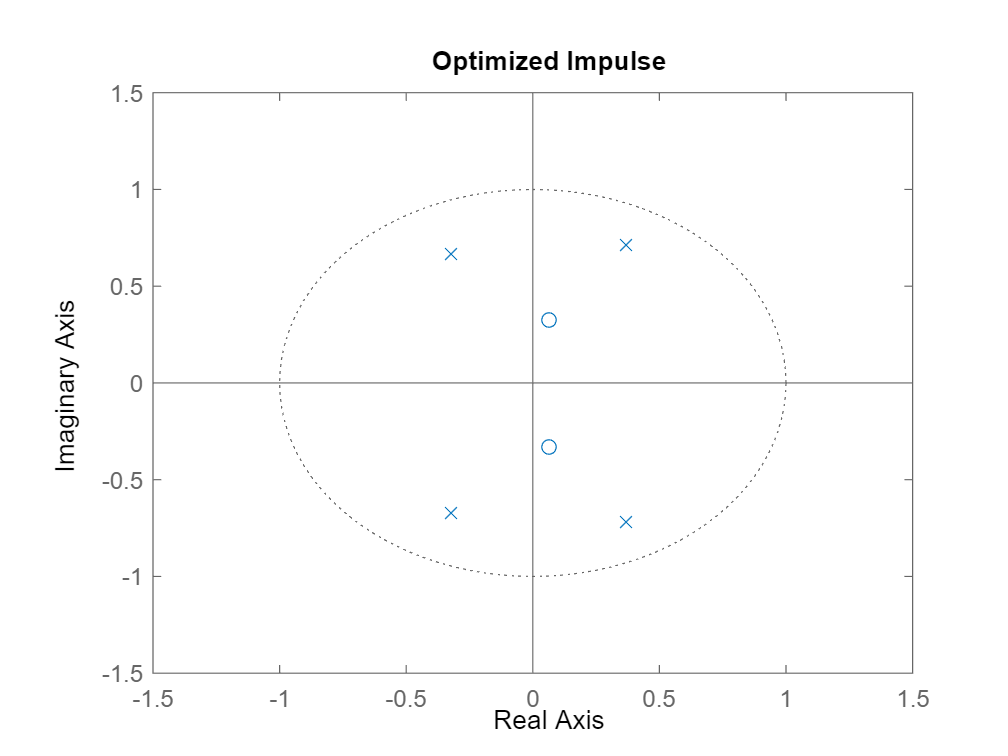

pzplot(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Optimized Impulse")

tf(newsys)

ans =
 
                                         
  0.04459 z^3 + 0.6086 z^2 - 0.07631 z   
                                         
                                + 0.06971
                                         
  ---------------------------------------
                                         
  z^4 - 0.0984 z^3 + 0.7306 z^2          
                                         
                    + 0.008211 z + 0.3602
                                         
 
Sample time: 1 seconds
Discrete-time transfer function.



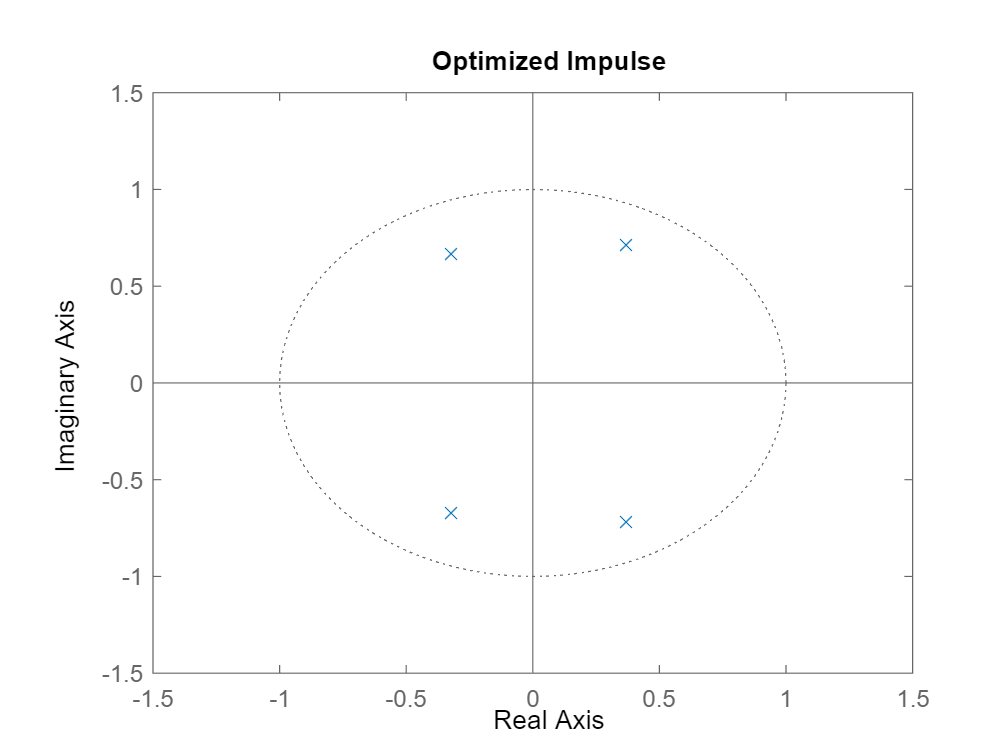

newsys = zpk([],pole(newsys),1,1);
pzplot(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Optimized Impulse")

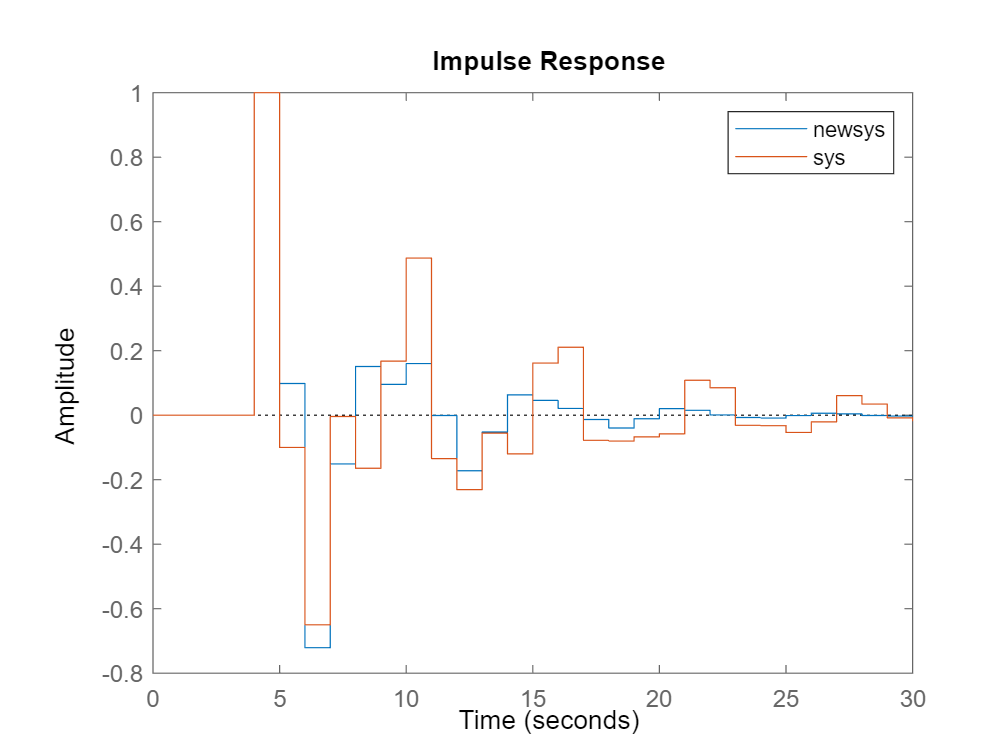

impulse(newsys,sys)
legend()
xlim([0,30])

ss(sys)

ans =
 
  A = 
            x1       x2       x3
   x1     -0.5        1        0
   x2     -0.5     -0.5        1
   x3        0        0     0.45
   x4        0        0  -0.6075
 
            x4
   x1        0
   x2        0
   x3        1
   x4     0.45
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



zero(sys)


ans =

  0×1 empty double column vector



pole(sys)

ans =    0.4500 - 0.7794i
   0.4500 + 0.7794i
  -0.5000 + 0.7071i
  -0.5000 - 0.7071i


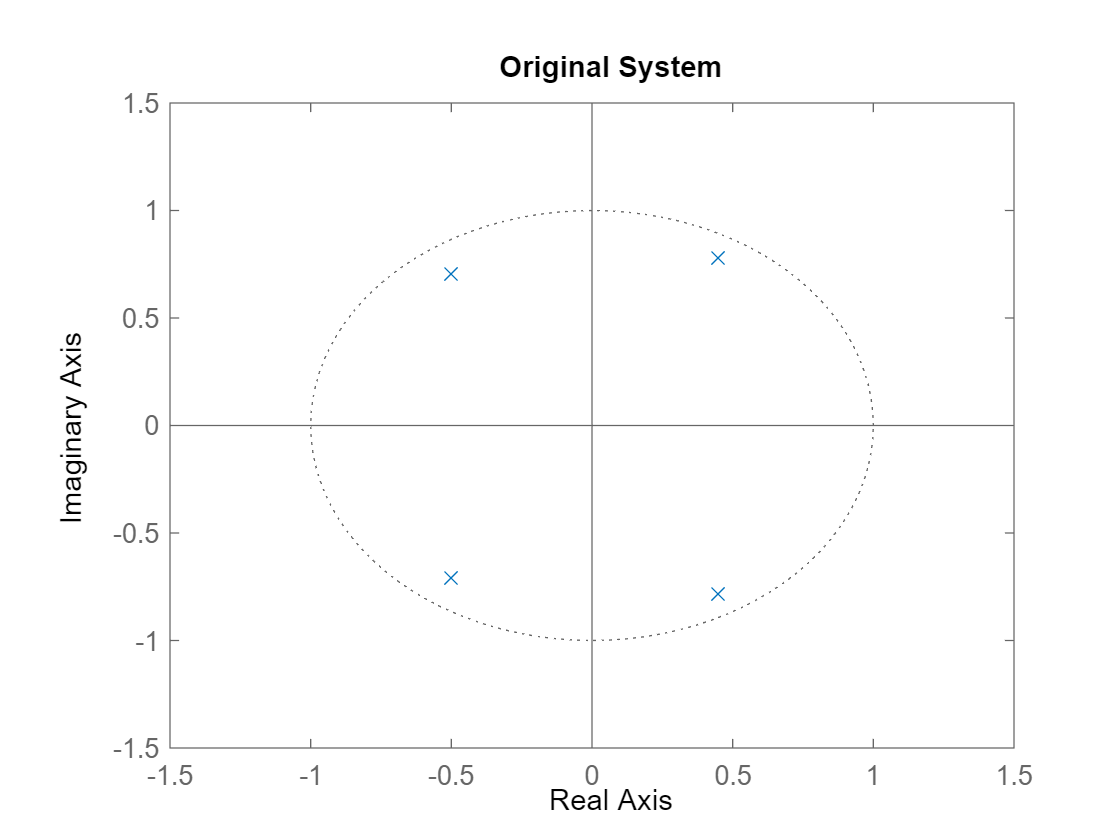

pzplot(sys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Original System")

## **MIMO System**

A = [0.7 0; 0 0.98];
B = [-0.1, 0.9, 0.8; 0.9, -0.5, -0.4];
C = [0.5, 0.2; 0.6, -0.8];
D = B.*0

D =      0     0     0
     0     0     0


sys2 = ss(A,B,C,D,0.05)

sys2 =
 
  A = 
         x1    x2
   x1   0.7     0
   x2     0  0.98
 
  B = 
         u1    u2    u3
   x1  -0.1   0.9   0.8
   x2   0.9  -0.5  -0.4
 
  C = 
         x1    x2
   y1   0.5   0.2
   y2   0.6  -0.8
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Sample time: 0.05 seconds
Discrete-time state-space model.



y2 = impulse(sys2,5);
rng(1991)
y2_noisy = y2 + 0.1*randn(size(y2));

y2(:,:,3)

ans =          0         0
    6.4000   16.0000
    4.0320   12.9920
    2.3834   10.8506
    1.2381    9.3164
    0.4450    8.2081
   -0.1017    7.3986
   -0.4762    6.7988
   -0.7302    6.3466
   -0.9000    5.9983


3 inputs, 2 outputs

y2(1:4,:,:)

ans = ans(:,:,1) =

         0         0
    2.6000  -15.6000
    2.8280  -14.9520
    2.9674  -14.4178


ans(:,:,2) =

         0         0
    7.0000   18.8000
    4.3400   15.4000
    2.4892   12.9752


ans(:,:,3) =

         0         0
    6.4000   16.0000
    4.0320   12.9920
    2.3834   10.8506


H{2}

ans =     2.6000    7.0000    6.4000
  -15.6000   18.8000   16.0000


for i=1:101
    H{i} = squeeze(y2(i,:,:));
end
BH = cell2mat(H(hankel(2:21,21:40)))

BH =     2.6000    7.0000    6.4000    2.8280    4.3400    4.0320    2.9674    2.4892    2.3834    3.0453    1.2046    1.2381    3.0804    0.3162    0.4450    3.0860   -0.2952   -0.1017    3.0714   -0.7128   -0.4762    3.0429   -0.9951   -0.7302    3.0051   -1.1827   -0.9000    2.9611   -1.3043   -1.0112    2.9132   -1.3799   -1.0813    2.8629   -1.4235   -1.1230    2.8111   -1.4449   -1.1448    2.7588   -1.4508   -1.1529    2.7063   -1.4462   -1.1516    2.6541   -1.4344   -1.1437    2.6023   -1.4177
  -15.6000   18.8000   16.0000  -14.9520   15.4000   12.9920  -14.4178   12.9752   10.8506  -13.9648   11.2339    9.3164  -13.5702    9.9720    8.2081  -13.2181    9.0465    7.3986  -12.8973    8.3573    6.7988  -12.5998    7.8344    6.3466  -12.3202    7.4287    5.9983  -12.0544    7.1058    5.7234  -11.7997    6.8417    5.5004  -11.5543    6.6194    5.3145  -11.3165    6.4272    5.1551  -11.0855    6.2568    5.0148  -10.8606    6.1024    4.8884  -10.6411    5.9598    4.7724  -10.4267    

svd(BH)

ans =   260.9026
   31.0698
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


r=2

r = 2

[U,S,V] = svd(BH);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-2,:)\Gamma(3:end,:)

A =     0.9728   -0.0426
   -0.0462    0.7072


C = Gamma(1:2,:)

C =    -0.5605    2.8847
    4.6411    2.6318


B = Delta(:,1:3)

B =    -3.4880    2.4093    1.9721
    0.2236    2.8947    2.6017


recovered = ss(A,B,C,B.*0,0.05)

recovered =
 
  A = 
             x1        x2
   x1    0.9728   -0.0426
   x2  -0.04618    0.7072
 
  B = 
           u1      u2      u3
   x1  -3.488   2.409   1.972
   x2  0.2236   2.895   2.602
 
  C = 
            x1       x2
   y1  -0.5605    2.885
   y2    4.641    2.632
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Sample time: 0.05 seconds
Discrete-time state-space model.



y3=impulse(recovered,5)

y3 = y3(:,:,1) =

         0         0
   52.0000 -312.0000
   56.5600 -299.0400
   59.3488 -288.3552
   60.9058 -279.2953
   61.6085 -271.4044
   61.7209 -264.3629
   61.4277 -257.9462
   60.8580 -251.9967
   60.1020 -246.4033
   59.2228 -241.0878
   58.2643 -235.9949
   57.2572 -231.0852
   56.2228 -226.3306
   55.1758 -221.7110
   54.1266 -217.2117
   53.0820 -212.8218
   52.0470 -208.5335
   51.0246 -204.3405
   50.0172 -200.2381
   49.0260 -196.2224
   48.0518 -192.2902
   47.0952 -188.4391
   46.1565 -184.6665
   45.2355 -180.9706
   44.3324 -177.3493
   43.4468 -173.8011
   42.5786 -170.3241
   41.7275 -166.9170
   40.8934 -163.5782
   40.0758 -160.3064
   39.2744 -157.1000
   38.4891 -153.9579
   37.7194 -150.8786
   36.9650 -147.8610
   36.2258 -144.9037
   35.5013 -142.0056
   34.7913 -139.1654
   34.0955 -136.3821
   33.4136 -133.6545
   32.7453 -130.9814
   32.0904 -128.3617
   31.4486 -125.7945
   30.8196 -123.2786
   30.2033 -120.8130
   29.5992 -118.3968
   29.0072 -116.

tf(recovered)

ans =
 
  From input 1 to output...
           2.6 z - 1.54
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
         -15.6 z + 11.26
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
  From input 2 to output...
            7 z - 7.42
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
          18.8 z - 16.18
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
  From input 3 to output...
           6.4 z - 6.72
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
           16 z - 13.89
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
Sample time: 0.05 seconds
Discrete-time transfer function.



tf(sys2)

ans =
 
  From input 1 to output...
          0.13 z - 0.077
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
         -0.78 z + 0.5628
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
  From input 2 to output...
          0.35 z - 0.371
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
         0.94 z - 0.8092
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
  From input 3 to output...
          0.32 z - 0.336
   1:  --------------------
       z^2 - 1.68 z + 0.686
 
          0.8 z - 0.6944
   2:  --------------------
       z^2 - 1.68 z + 0.686
 
Sample time: 0.05 seconds
Discrete-time transfer function.



for i=1:101
    H_n{i} = squeeze(y2_noisy(i,:,:));
end
BH_n = cell2mat(H_n(hankel(2:21,21:40)))

BH_n =     2.6920    6.9410    6.4270    2.8430    4.4254    3.7756    3.1079    2.3039    2.4299    3.1487    1.1839    1.4234    3.1096    0.3432    0.5489    3.0083   -0.3605   -0.0106    3.1281   -0.6651   -0.5001    2.9046   -1.0022   -0.7121    3.0295   -1.2765   -0.8756    3.0420   -1.2882   -1.0015    2.9345   -1.4067   -1.1644    2.9508   -1.4645   -1.1582    3.0150   -1.5160   -1.1623    2.8512   -1.4447   -1.2010    2.7330   -1.6309   -1.0679    2.7183   -1.4742   -0.8899    2.6449   -1.4720
  -15.7533   18.8181   16.0828  -15.0618   15.5267   13.0138  -14.5593   12.9501   10.6596  -13.9588   11.2135    9.2627  -13.6113    9.7519    8.1779  -13.2549    8.9691    7.5799  -13.0334    8.2180    6.8903  -12.5219    7.7958    6.3409  -12.2762    7.4813    6.1292  -12.0634    7.2581    5.6189  -11.6976    7.0215    5.4656  -11.6417    6.6077    5.4558  -11.2751    6.3952    5.3053  -11.0507    6.3386    5.0878  -10.8257    6.1514    4.9375  -10.7140    6.0364    4.7138  -10.3940  

svd(BH_n)

ans =   261.8028
   31.0444
    1.2217
    1.1887
    1.1774
    1.1139
    1.0501
    1.0194
    0.9968
    0.9796
